Live Script for developing/testing background removal algorithms.

In particular we test the one Cheng suggested over email and the Eigenfaces algorithm

%Displaying some typical input images
disp('Here are some typical input images');

Here are some typical input images


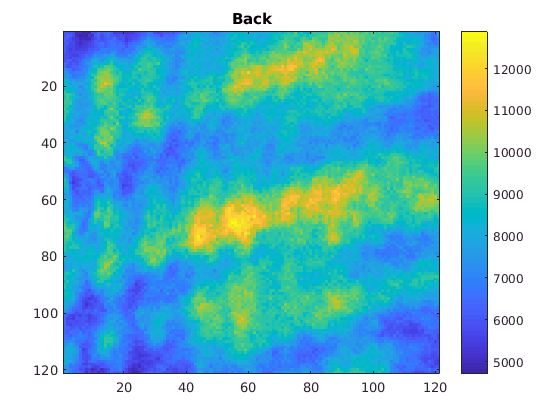

back=load_image('20170405/Cool100d100d80PGCZ4.4_1_back.ascii');
plot_image(back,'Back');

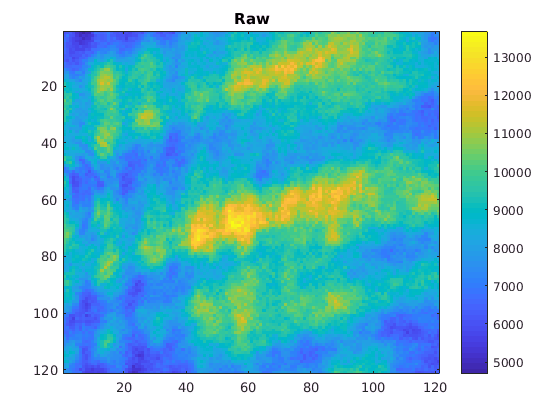


raw=load_image('20170405/Cool100d100d80PGCZ4.4_1_raw.ascii');
plot_image(raw,'Raw');

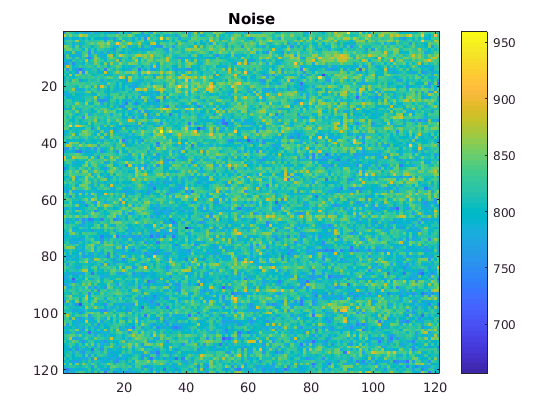


noise=load_image('20170405/Cool100d100d80PGCZ4.4_1_noise.ascii');
plot_image(noise,'Noise');

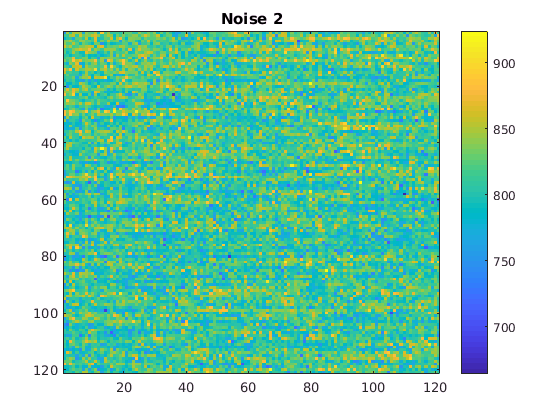


noise2=load_image('20170405/Cool100d100d80PGCZ4.4_2_noise.ascii');
plot_image(noise2,'Noise 2');

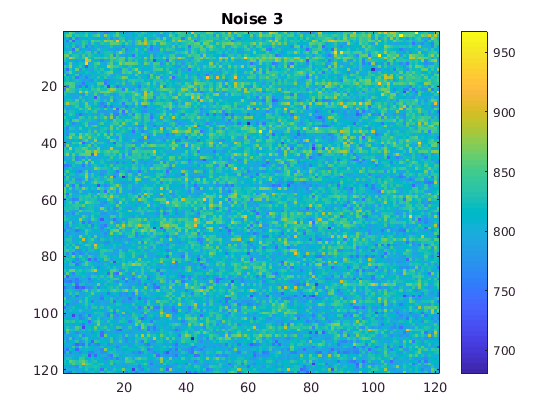


noise3=load_image('20170405/Cool100d100d80PGCZ4.4_3_noise.ascii');
plot_image(noise3,'Noise 3');

%Now show some typical basis vectors from Cheng's algorithm and Eigenfaces
ls_pattern=fullfile('20170405','Savefile_4*_back.ascii'); %regex pattern to match images for basis
max_vectors=10; %Maximum number of vectors to use for basis
indices=1:10; %Number of basis vectors to plot

file_list=get_file_list(ls_pattern);
back_region=ones(size(load_image(file_list{1}))); %need back region to pecify max_vectors
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);
basis_eigen=make_basis_eig(file_list,back_region,max_vectors);
%Plot basis vectors
k_max=min(max_vectors,length(indices));
disp('Algorithm from Cheng basis');

Algorithm from Cheng basis


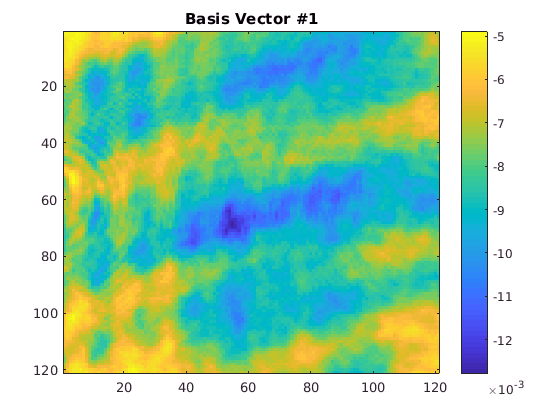

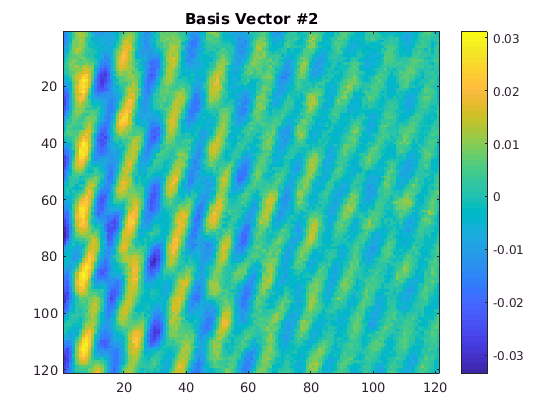

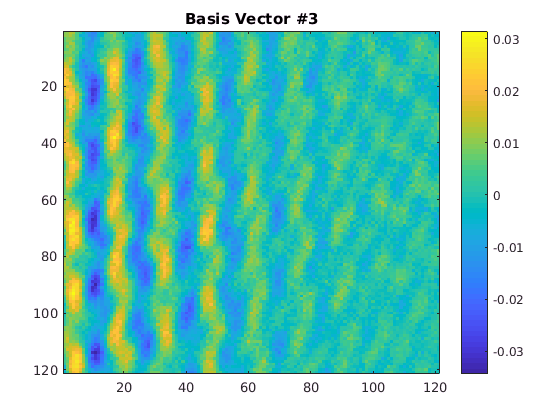

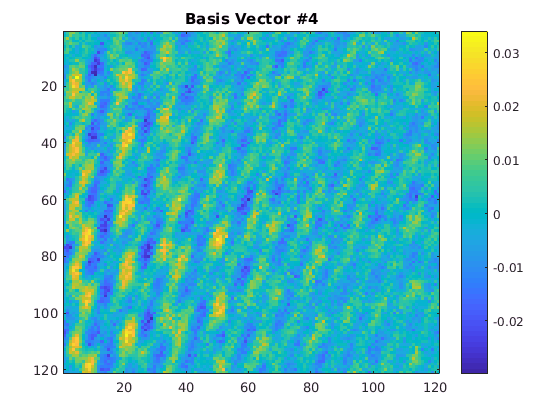

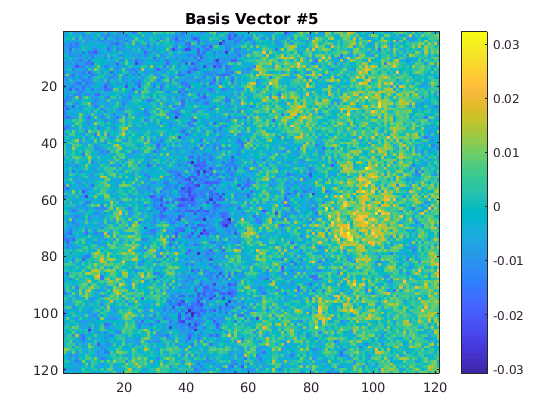

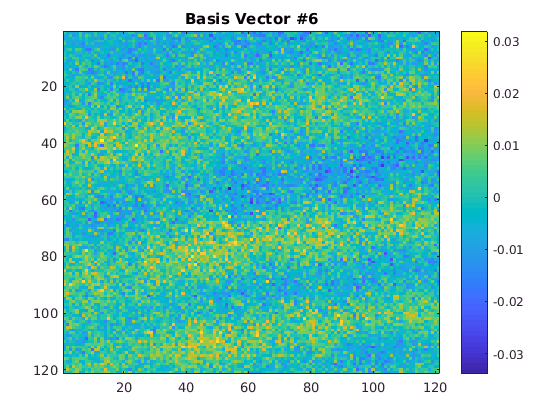

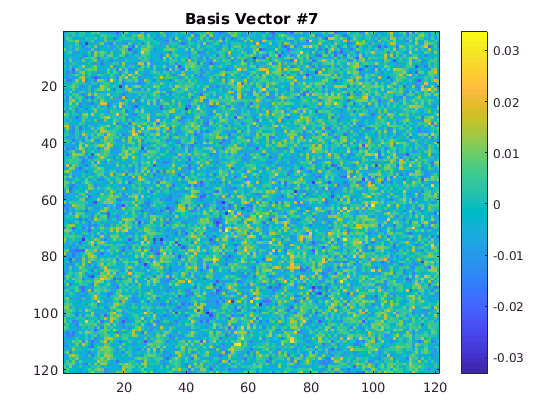

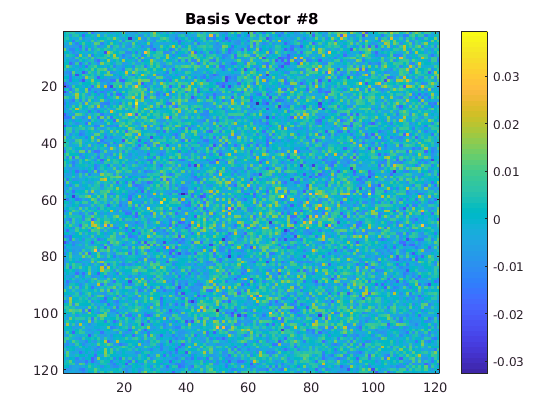

plot_basis_vectors(basis_cheng,1:k_max);

disp('Algorithm from Eigenface basis');

Algorithm from Eigenface basis


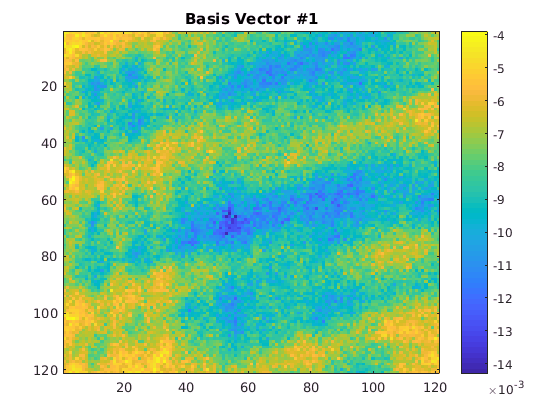

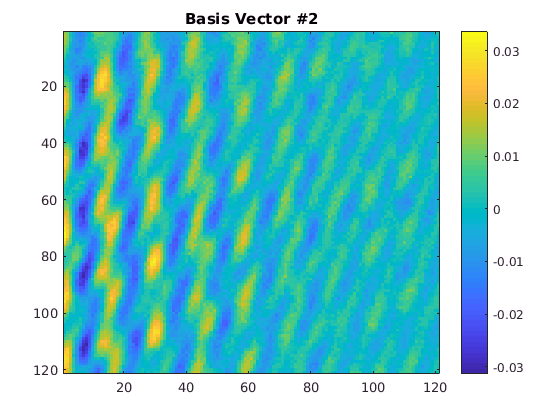

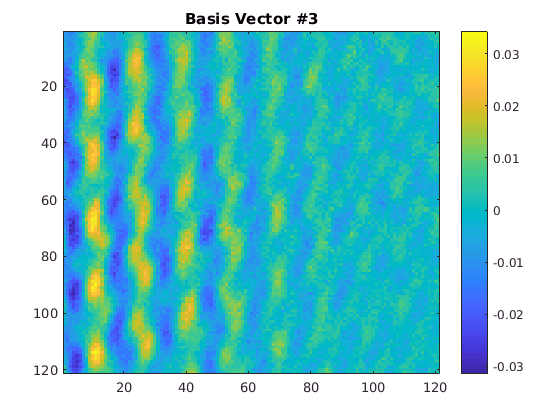

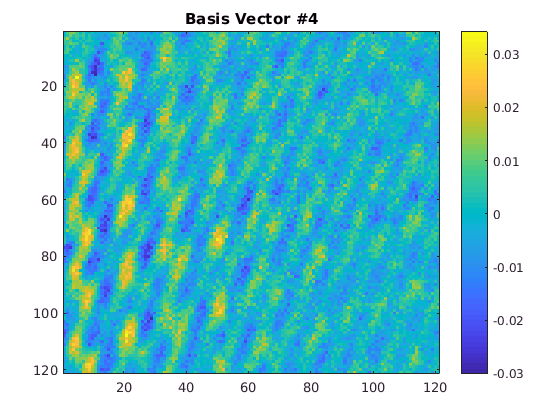

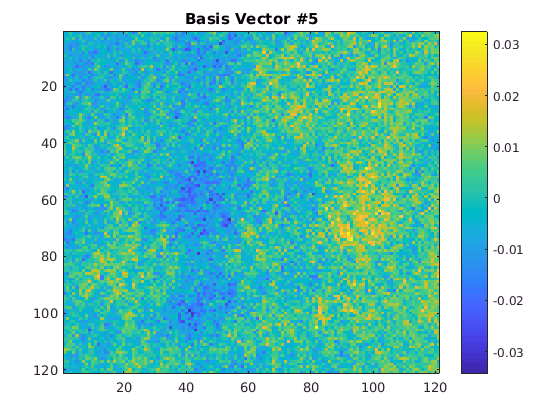

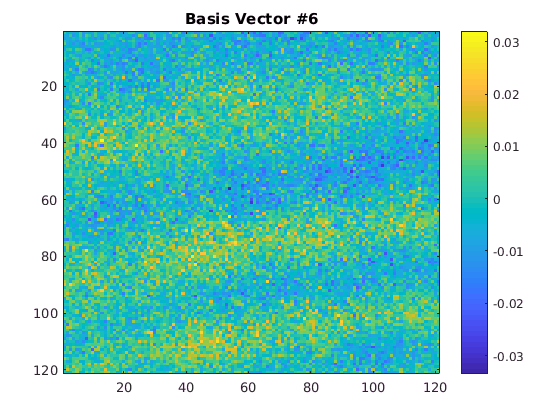

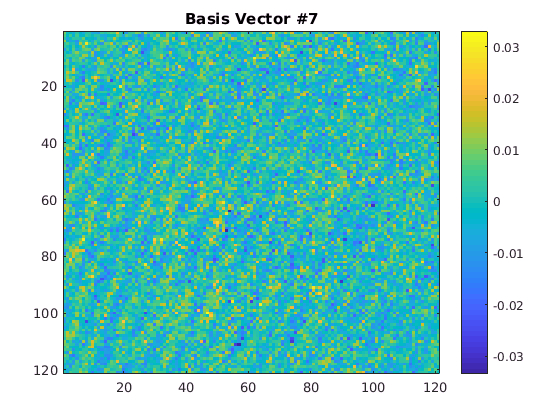

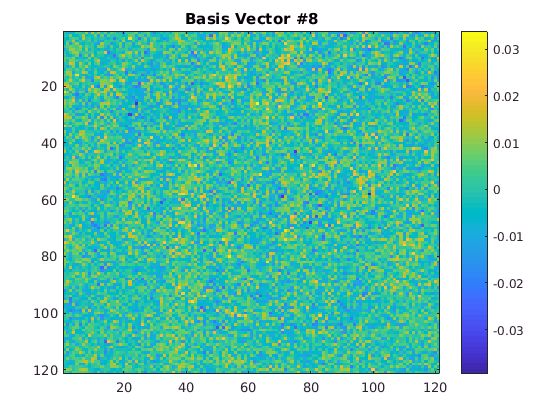

plot_basis_vectors(basis_eigen,1:k_max);

%Looking at residuals for picture 412 using differnt pictures to form basis
disp('Using more or less recent images to make a basis (Cheng Algorithm)');

Using more or less recent images to make a basis (Cheng Algorithm)


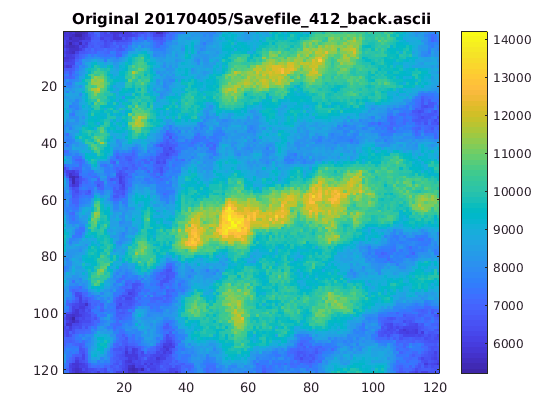

filename=fullfile('20170405','Savefile_412_back.ascii');
% filename=fullfile('20170405','Cool100d100d80PGCZ4.4_1_back.ascii');
max_vectors=20; %Maximum number of vectors to use for basis
filename_pattern=fullfile('20170405','Savefile_%d_back.ascii');

image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,['Original ',filename]); %Plot original

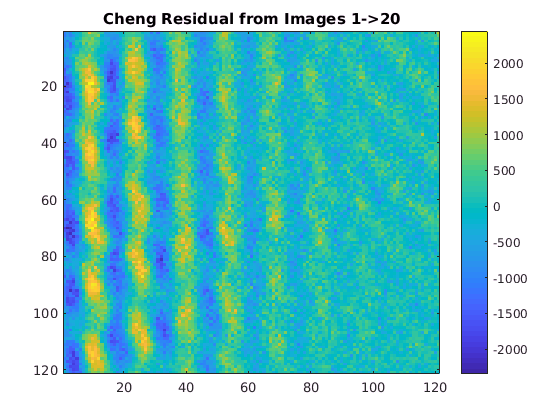

back_region=ones(size(image_in)); %We'll use the full image

%Let's try to re-construct it with the first 20 pictures of that series
k_list=1:20;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Cheng Residual from Images 1->20'); %Plot the residual

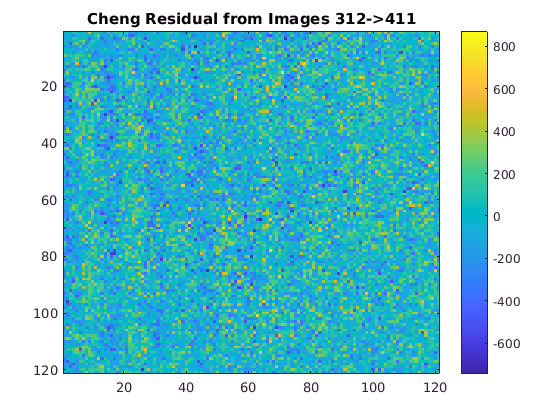


%Now let's try to re-construct it with the 20 pictures right before it
k_list=392:411;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Cheng Residual from Images 312->411'); %Plot the residual background

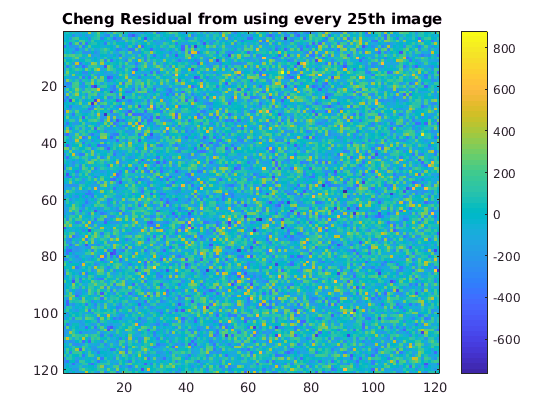


%Now let's try to re-construct it with 20 evenly spaced pictures
k_list=25*(1:20);
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Cheng Residual from using every 25th image'); %Plot the residual background

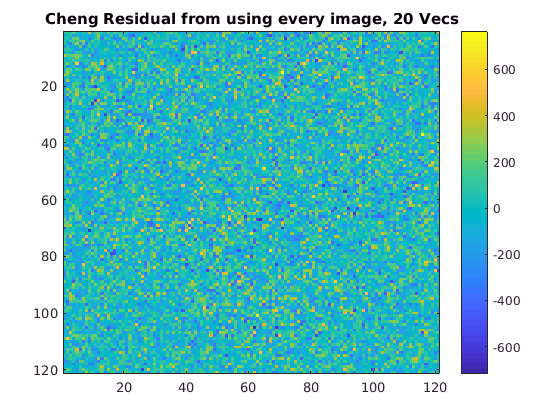


%Now let's try using all 500 images to make only 20 basis vectors
k_list=1:500;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Cheng Residual from using every image, 20 Vecs'); %Plot the residual background

% %This is the cell that tried to use v1 to ignore the bottom half.
% %It didn't work but has been surpassed by version 2
% %Doing same thing except ignoring bottom half of image
% filename='Savefile_412_back.ascii';
% atom_region=[61,121,1,121];
% max_vectors=20; %Maximum number of vectors to use for basis
% filename_pattern='Savefile_%d_back.ascii';
%
% image_in=load_image(filename); %Get data for the background we are re-constructing
% plot_image(image_in,'Original'); %Plot original
%
% %Let's try to re-construct it with the first 20 pictures of that series
% k_list=1:20;
% file_list=indices_to_file_list(filename_pattern,k_list);
% basis=make_basis1(file_list,max_vectors);
% residual=get_residual1(image_in,basis,atom_region); %Do projection and subtract the projection from the image
% plot_image(residual,'Residual from Images 1->20 Ignoring bottom half'); %Plot the residual
%
% %Now let's try to re-construct it with the 20 pictures right before it
% k_list=392:411;
% file_list=indices_to_file_list(filename_pattern,k_list);
% basis=make_basis1(file_list,max_vectors);
% residual=get_residual1(image_in,basis,atom_region); %Do projection and subtract the projection from the image
% plot_image(residual,'Residual from Images 392->411 Ignoring bottom half'); %Plot the residual background
%
% %Now let's try to re-construct it with 20 evenly spaced pictures
% k_list=25*(1:20);
% file_list=indices_to_file_list(filename_pattern,k_list);
% basis=make_basis1(file_list,max_vectors);
% residual=get_residual1(image_in,basis,atom_region); %Do projection and subtract the projection from the image
% plot_image(residual,'Residual from using every 25th image Ignoring bottom half'); %Plot the residual background

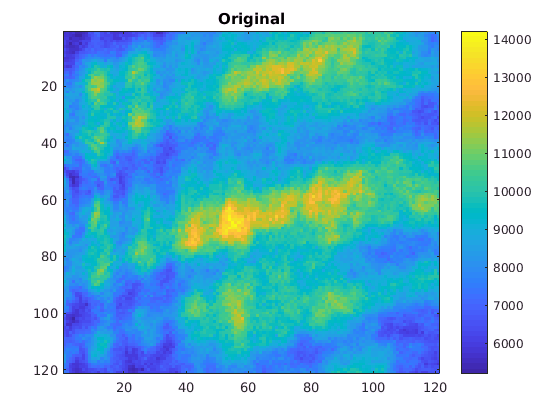

%Doing same thing except ignoring bottom half of image with v2 which does better normalization when ignoring regions
filename=fullfile('20170405','Savefile_412_back.ascii');
% filename=fullfile('20170405','Cool100d100d80PGCZ4.4_1_back.ascii');
row_min=61; row_max=121; col_min=1; col_max=121;
max_vectors=20; %Maximum number of vectors to use for basis
filename_pattern=fullfile('20170405','Savefile_%d_back.ascii');

image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,'Original'); %Plot original

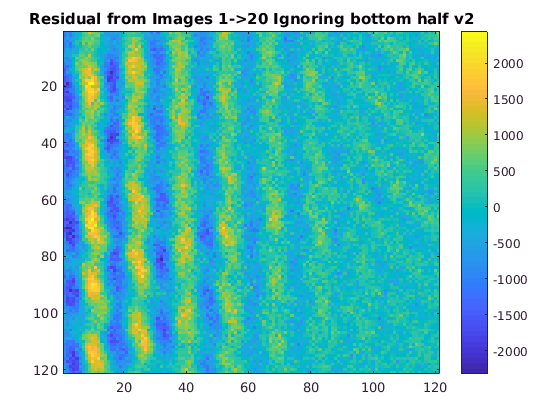


%Creat back_region to mark the bottom half of the image
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
%Let's try to re-construct it with the first 20 pictures of that series
k_list=1:20;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Residual from Images 1->20 Ignoring bottom half v2'); %Plot the residual

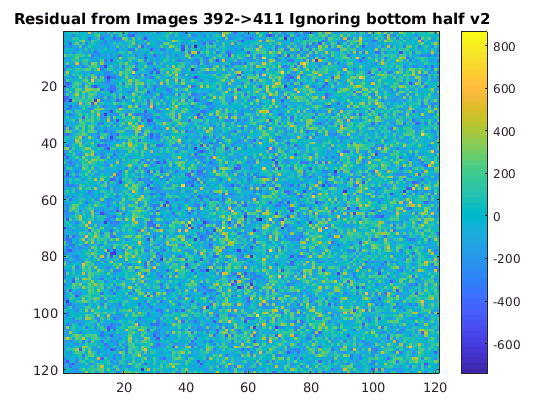


%Now let's try to re-construct it with the 20 pictures right before it
k_list=392:411;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Residual from Images 392->411 Ignoring bottom half v2'); %Plot the residual

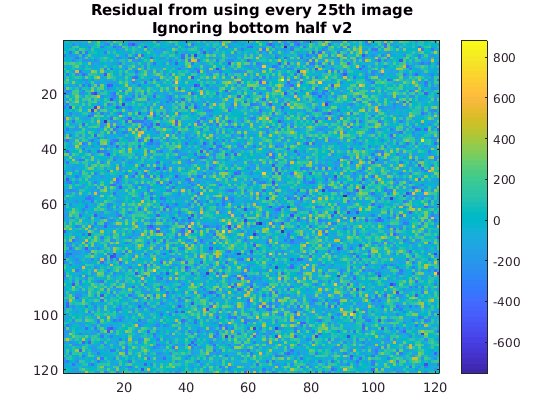


%Now let's try to re-construct it with 20 evenly spaced pictures
k_list=25*(1:20);
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,{'Residual from using every 25th image','Ignoring bottom half v2'}); %Plot the residual

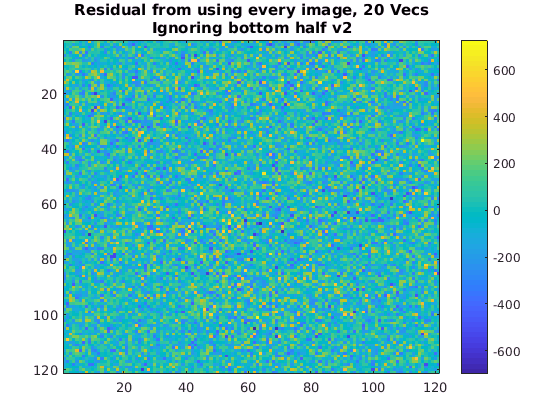


%Now let's try using all 500 images to make only 20 basis vectors
k_list=1:500;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng( file_list, back_region, max_vectors);
residual=get_residual_cheng(image_in,basis_cheng,back_region); %Do projection and subtract the projection from the image
plot_image(residual,{'Residual from using every image, 20 Vecs','Ignoring bottom half v2'}); %Plot the residual background

indices=1:10;
%Plot basis vectors (the first k_max of them)
%plot_basis_vectors( basis_cheng, indices )

disp('For reference we can see what Poissonian noise looks like');

For reference we can see what Poissonian noise looks like


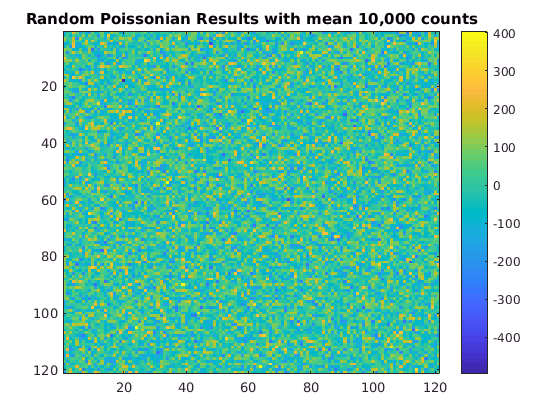

poiss_noise=poissrnd(10e3,121,121)-10e3;
plot_image(poiss_noise,'Random Poissonian Results with mean 10,000 counts');

%Now let's try comparing this technique with the old one for real data
disp('Checking effects from not ignoring atom region');

Checking effects from not ignoring atom region


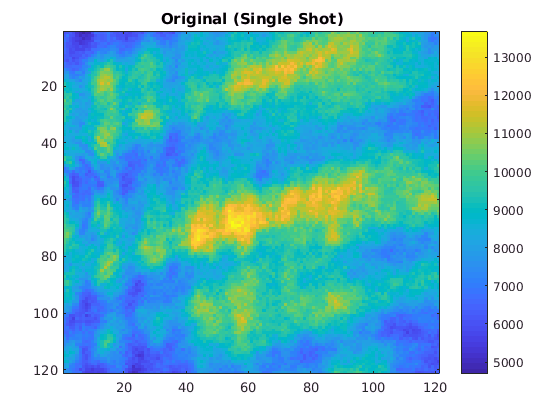

image_name=fullfile('20170405','Cool100d100d80PGCZ4.4_1');
filename=[image_name,'_raw.ascii'];
row_min=40; row_max=60; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis
filename_pattern=fullfile('20170405','Cool100d100d80PGCZ4.4_%d_back.ascii');
k_list=1:15;

image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,'Original (Single Shot)'); %Plot original

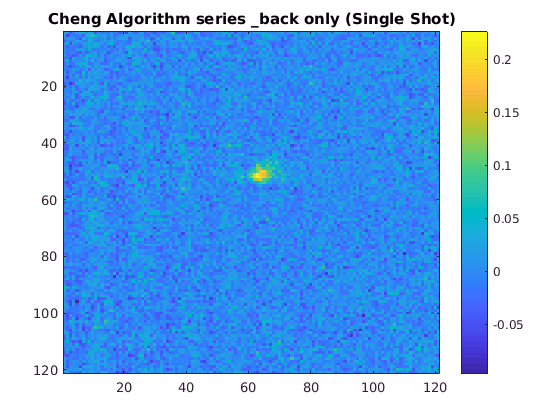


%Old technique
% OD_simple=get_OD_simple(image_name);
% plot_image(OD_simple,'Old Algorithm (Single Shot)');

%Cheng's technique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);
OD_chenga=get_OD_cheng(image_in,basis_cheng,back_region);
plot_image(OD_chenga,'Cheng Algorithm series _back only (Single Shot)');

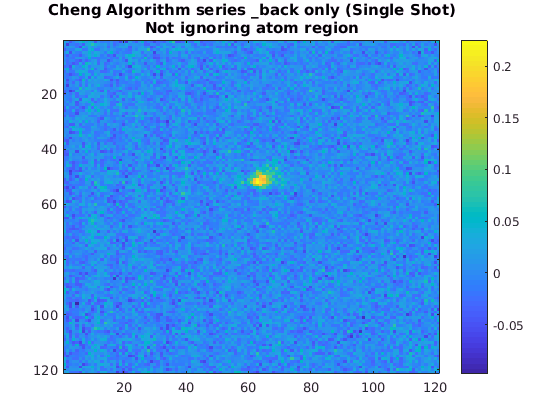



%Cheng's technique without ignoring atom region
file_list=indices_to_file_list(filename_pattern,k_list);
basis_cheng=make_basis_cheng(file_list);
OD_chengb=get_OD_cheng(image_in,basis_cheng);
plot_image(OD_chengb,{'Cheng Algorithm series _back only (Single Shot)','Not ignoring atom region'});

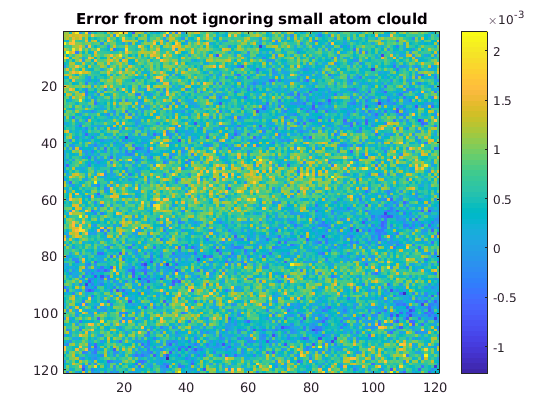


%Difference between ignoring atoms or not ignoring them (for this picture)
plot_image(OD_chenga-OD_chengb,'Error from not ignoring small atom clould');

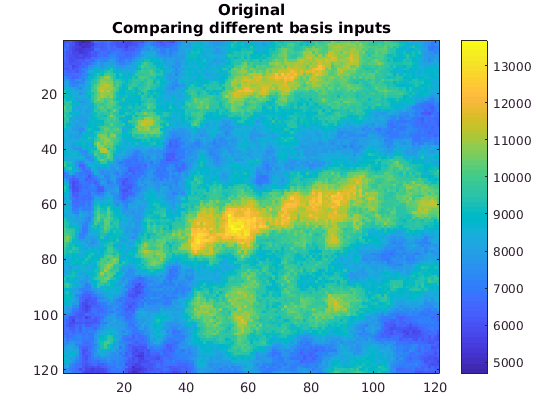

%Real Data again, but now let's use more or fewer basis images
image_name=fullfile('20170405','Cool100d100d80PGCZ4.4_1');
% filename=fullfile('20170405','Savefile_412_raw.ascii');
filename=[image_name,'_raw.ascii'];
row_min=40; row_max=60; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%To use just the background for this single shot, uncomment line below
% file_list={[image_name,'_back.ascii']};
%Background data from this series
filename_pattern1=fullfile('20170405','Cool100d100d80PGCZ4.4_%d_back.ascii');
k_list1=1:15;
file_list1=indices_to_file_list(filename_pattern1,k_list1);
%Background data from another, much longer series
filename_pattern2=fullfile('20170405','Savefile_%d_back.ascii');
% k_list2=20*(1:25);
k_list2=1:500;
file_list2=indices_to_file_list(filename_pattern2,k_list2);
%Uncomment one of the lines below to decide which _back data to use
file_list=file_list1;
% file_list=file_list2;
% file_list=[file_list1;file_list2];

%Plot raw data for reference
image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,{'Original','Comparing different basis inputs'}); %Plot original

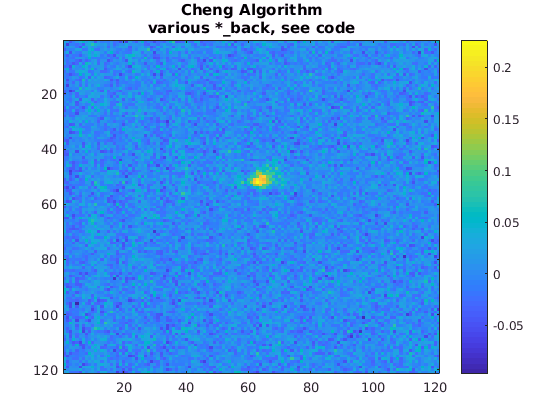


%Old technique
OD_simple=get_OD_simple(image_name);
% plot_image(OD_simple,'Old Algorithm');

%Cheng's technique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);
OD_cheng=get_OD_cheng(image_in,basis_cheng,back_region);
plot_image(OD_cheng,{'Cheng Algorithm','various *_back, see code'});

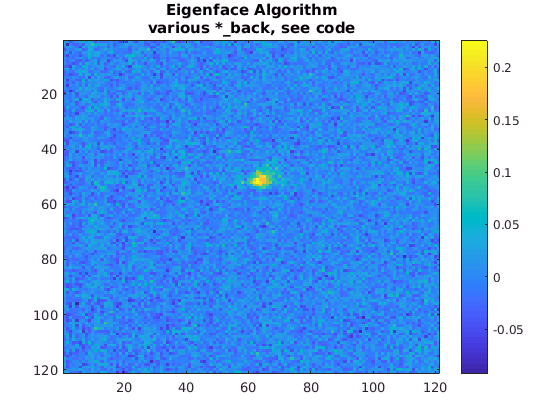


%Eigenfaces technique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eig=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_image(OD_eig,{'Eigenface Algorithm','various *_back, see code'});

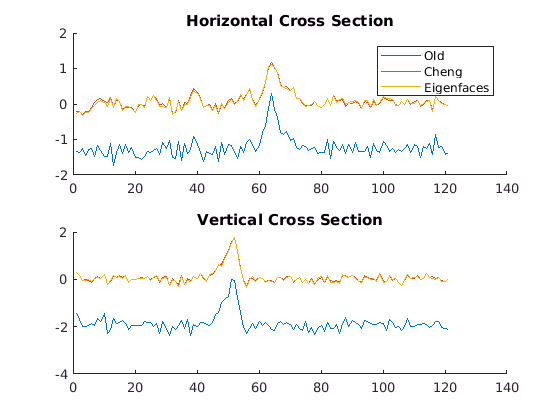


%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_simple,'Old',limits,fig);
plot_cross_sections(OD_cheng,'Cheng',limits,fig);
plot_cross_sections(OD_eig,'Eigenfaces',limits,fig);

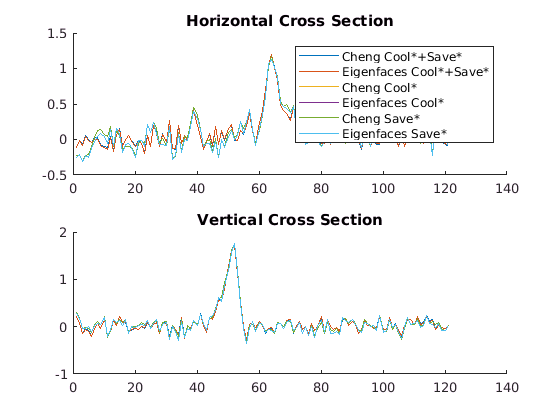

fig=figure();

%Cool* and Save* data
file_list=[file_list1;file_list2];
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);
OD_chengcs=get_OD_cheng(image_in,basis_cheng,back_region);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eigcs=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_cross_sections(OD_chengcs,'Cheng Cool*+Save*',limits,fig);
plot_cross_sections(OD_eigcs,'Eigenfaces Cool*+Save*',limits,fig);

%Now just the Cool*_back.ascii data
file_list=file_list1;
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);
OD_chengc=get_OD_cheng(image_in,basis_cheng,back_region);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eigc=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_cross_sections(OD_chengc,'Cheng Cool*',limits,fig);
plot_cross_sections(OD_eigc,'Eigenfaces Cool*',limits,fig);

%Now just the Save*_back.ascii data
file_list=file_list1;
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);
OD_chengs=get_OD_cheng(image_in,basis_cheng,back_region);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eigs=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_cross_sections(OD_chengs,'Cheng Save*',limits,fig);
plot_cross_sections(OD_eigs,'Eigenfaces Save*',limits,fig);

%Now using real data that may actually make it into the paper
%This set has no_atoms data to help our old algorithm
disp('Comparing to old Algorithm for many shots averaged');

Comparing to old Algorithm for many shots averaged


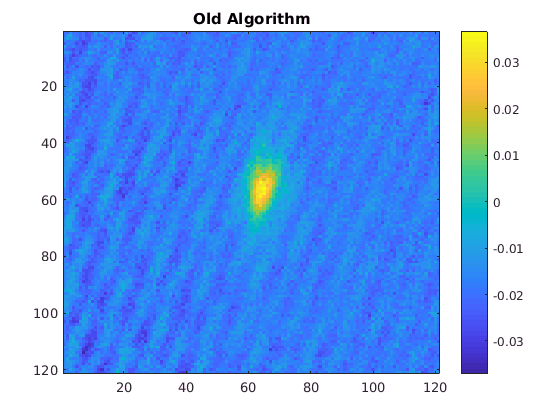

image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
no_atom_name=fullfile('20170406','NoAtoma1');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Old technique
OD_simple=load_image([image_name,'.txt']);
no_atom=load_image([no_atom_name,'.txt']);
plot_image(OD_simple,'Old Algorithm');

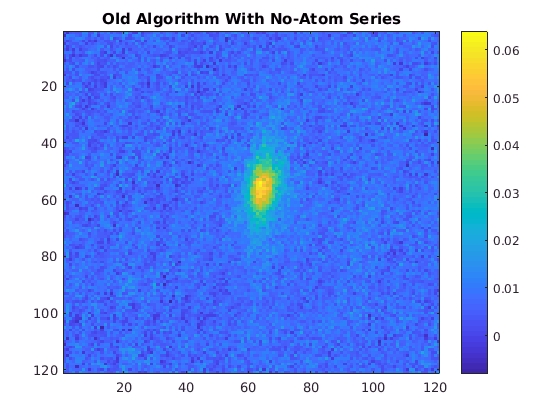

OD_simple=OD_simple-no_atom;
plot_image(OD_simple,'Old Algorithm With No-Atom Series');

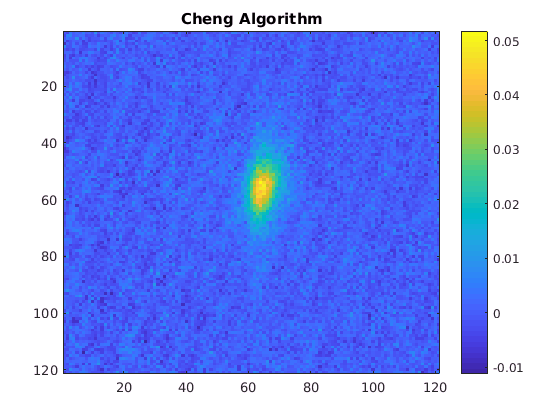


%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
% k_list1=7*(1:20);
file_list1=indices_to_file_list(filename_pattern1,k_list1);
filename_pattern2=[no_atom_name,'_%d_back.ascii'];
k_list2=1:200;
% k_list2=10*(1:20);
file_list2=indices_to_file_list(filename_pattern2,k_list2);
% file_list=file_list1; %back data from this series only
% file_list=file_list2; %back data from the no-atom series only
file_list=[file_list1;file_list2]; %Both this series and no-atom series


% %Cheng's technique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);

%Make list of images with atoms, remove background from each, then average
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
k_max=length(atom_file_list);
[n_rows, n_cols]=size( load_image(file_list{1}) );
OD_cheng_array=zeros(n_rows,n_cols,k_max);
for k=1:k_max
    filename=atom_file_list{k};
    image_in=load_image(filename);
    OD_cheng_array(:,:,k)=get_OD_cheng(image_in,basis_cheng,back_region);
end
OD_cheng=mean(OD_cheng_array,3);
plot_image(OD_cheng,'Cheng Algorithm');

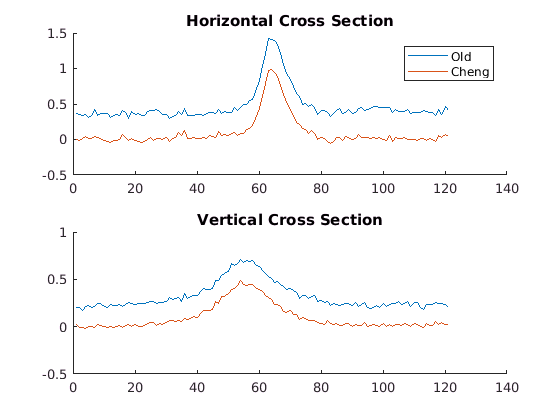


%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_simple,'Old',limits,fig);
plot_cross_sections(OD_cheng,'Cheng',limits,fig);

%Seeing if averaging the raw images before or after background removal changes anything
disp('Comparing doing background removal before or after averaging images');

Comparing doing background removal before or after averaging images


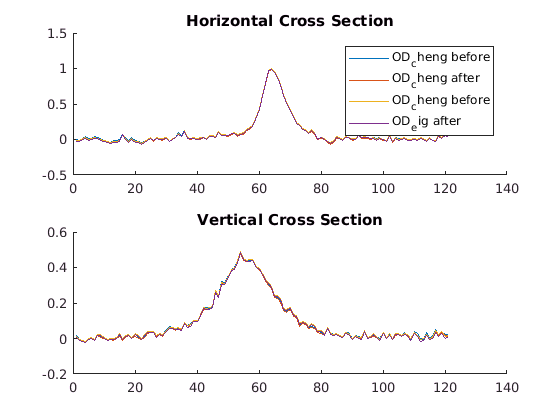

image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
no_atom_name=fullfile('20170406','NoAtoma1');
% filename=[image_name,'_raw.ascii'];
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=10; %Maximum number of vectors to use for basis

%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
% k_list1=7*(1:20);
file_list1=indices_to_file_list(filename_pattern1,k_list1);
filename_pattern2=[no_atom_name,'_%d_back.ascii'];
k_list2=1:200;
% k_list2=10*(1:20);
file_list2=indices_to_file_list(filename_pattern2,k_list2);
% file_list=file_list1; %back data from this series only
% file_list=file_list2; %back data from the no-atom series only
file_list=[file_list1;file_list2]; %Both this series and no-atom series

%Cheng's technique
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_cheng=make_basis_cheng(file_list,back_region,max_vectors);
[basis_eig,mean_back,~]=make_basis_eig(file_list,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
k_max=length(atom_file_list);
[n_rows, n_cols]=size( load_image(file_list{1}) );
raw_array=zeros(n_rows,n_cols,k_max);
OD_cheng_array=zeros(n_rows,n_cols,k_max);
OD_eig_array=zeros(n_rows,n_cols,k_max);
for k=1:k_max
    filename=atom_file_list{k};
    image_in=load_image(filename);
    raw_array(:,:,k)=image_in;
    OD_cheng_array(:,:,k)=get_OD_cheng(image_in,basis_cheng,back_region);
    OD_eig_array(:,:,k)=get_OD_eig(image_in,basis_eig,mean_back,back_region);
end
raw_mean=mean(raw_array,3);
OD_cheng_before=mean(OD_cheng_array,3);
OD_eig_before=mean(OD_eig_array,3);
OD_cheng_after=get_OD_cheng(raw_mean,basis_cheng,back_region);
OD_eig_after=get_OD_eig(raw_mean,basis_eig,mean_back,back_region);

%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_cheng_before,'OD_cheng before',limits,fig);
plot_cross_sections(OD_cheng_after,'OD_cheng after',limits,fig);
plot_cross_sections(OD_eig_before,'OD_cheng before',limits,fig);
plot_cross_sections(OD_eig_after,'OD_eig after',limits,fig);

%Mega-basis using all the _back images
disp('Seeing if using all the */*_back.ascii files improves the image');

Seeing if using all the */*_back.ascii files improves the image


image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
back_file_pattern=fullfile('2017040*','*_back.ascii');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
file_list1=indices_to_file_list(filename_pattern1,k_list1);
file_list2=get_file_list(back_file_pattern);

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_cheng_small=make_basis_cheng(file_list1,back_region,max_vectors);
basis_cheng_big=make_basis_cheng(file_list2,back_region,max_vectors);
[basis_eig_small,mean_back_small,~]=make_basis_eig(file_list1,back_region,max_vectors);
[basis_eig_big,mean_back_big,~]=make_basis_eig(file_list2,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
raw_mean=get_mean_image(atom_file_list);
OD_cheng_small=get_OD_cheng(raw_mean,basis_cheng_small,back_region);
OD_cheng_big=get_OD_cheng(raw_mean,basis_cheng_big,back_region);
OD_eig_small=get_OD_eig(raw_mean,basis_eig_small,mean_back_small,back_region);
OD_eig_big=get_OD_eig(raw_mean,basis_eig_big,mean_back_big,back_region);

%Plot the resulting images
plot_image(OD_cheng_small,'Cheng Algorithm Small Basis Input');
plot_image(OD_cheng_big,'Cheng Algorithm Massive Basis Input');
plot_image(OD_eig_small,'Eigenfaces Small Basis Input');
plot_image(OD_eig_big,'Eigenfaces Massive Basis Input');

%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_cheng_small,'OD cheng small',limits,fig);
plot_cross_sections(OD_cheng_big,'OD cheng big',limits,fig);
plot_cross_sections(OD_eig_small,'OD eig small',limits,fig);
plot_cross_sections(OD_eig_big,'OD eig big',limits,fig);

%Let's compare some of the basis vectors from the two big bases
disp('Looking at basis vectors from the two different algorithms');
disp('They seem to be the same up to a factor of -1 except for the');
disp('first basis vector which may differ by mean_back');
% indices=1:20;
indices=[2];
%Plot basis vectors
plot_basis_vectors( basis_eig_big, indices );
plot_basis_vectors( basis_cheng_big, indices );

%Seeing if using every 10th image from the mega-basis gives similar results
disp('Seeing if using every 10th the */*_back.ascii files works as well');
image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
back_file_pattern=fullfile('2017040*','*_back.ascii');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
file_list1=indices_to_file_list(filename_pattern1,k_list1);
file_list2=get_file_list(back_file_pattern);
%shorten file_lists
% file_list1=file_list1(1:10:length(file_list1));
file_list10=file_list2(1:10:length(file_list2));

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_cheng_10=make_basis_cheng(file_list10,back_region,max_vectors);
% basis_cheng_big=make_basis_cheng(file_list2,back_region,max_vectors);
[basis_eig_10,mean_back_10,~]=make_basis_eig(file_list10,back_region,max_vectors);
% [basis_eig_big,mean_back_big,~]=make_basis_eig(file_list2,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
raw_mean=get_mean_image(atom_file_list);
OD_cheng_10=get_OD_cheng(raw_mean,basis_cheng_10,back_region);
OD_cheng_big=get_OD_cheng(raw_mean,basis_cheng_big,back_region);
OD_eig_10=get_OD_eig(raw_mean,basis_eig_10,mean_back_10,back_region);
OD_eig_big=get_OD_eig(raw_mean,basis_eig_big,mean_back_big,back_region);

%Plot the resulting images
plot_image(OD_cheng_10,'Cheng Algorithm Every 10th Basis Input');
plot_image(OD_cheng_big,'Cheng Algorithm Massive Basis Input');
plot_image(OD_eig_10,'Eigenfaces Every 10th Basis Input');
plot_image(OD_eig_big,'Eigenfaces Massive Basis Input');

%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_cheng_10,'OD cheng every 10th image',limits,fig);
plot_cross_sections(OD_cheng_big,'OD cheng big',limits,fig);
plot_cross_sections(OD_eig_10,'OD eig every 10th image',limits,fig);
plot_cross_sections(OD_eig_big,'OD eig big',limits,fig);

%Now that I'm very convinced Cheng and Eigenfaces give similar output, I'd
%like to figure out which one is fastest for large inputs
disp('Figuring out whether Cheng or Eigenfaces is faster for large input');
%Pick a file_list
file_list=file_list2;
%Make function handles so we can use timeit()
cheng=@() make_basis_cheng(file_list,back_region,max_vectors);
eig=@() make_basis_eig(file_list,back_region,max_vectors);
%Now let's time the functions
cheng_time=timeit(cheng,1); %1 because make_basis_eig has 1 output
eig_time=timeit(eig,3); %3 because make_basis_eig has 3 outputs
%Display the results
fprintf('Cheng took %f seconds\n',cheng_time);
fprintf('Eigenfaces took %f seconds\n',eig_time);

profile on
[a,b,c]=make_basis_eig(file_list,back_region,max_vectors);
profile off
profile viewer

profile on
a=make_basis_cheng(file_list,back_region,max_vectors);
profile off
profile viewer

fprintf('Turns out that eigenfaces is much faster.  With ~3000 images eigenfaces\n');
fprintf('it only takes 15 seconds and is mainly limited by how long it takes to\n');
fprintf('get the data off the hard drive.  The Cheng algorithm takes 30 seconds\n');
fprintf('and is not hard-drive limited for the same 3000 images data set (mainly\n');
fprintf('it is limited by how long svd() takes). This may partially be due to my\n');
fprintf('particular implementation, but either way I will just use eigenfaces now\n');
fprintf('\n\n\n\n');

%Now let's see if including the */*_noise.ascii images improves things at all
disp('Seeing if adding the */*_noise.ascii files to the basis input improves the results');
image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
back_file_pattern=fullfile('2017040*','*_back.ascii');
noise_file_pattern=fullfile('2017040*','*_noise.ascii');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists
file_list_back=get_file_list(back_file_pattern);
file_list_noise=get_file_list(noise_file_pattern);
file_list_both=[file_list_back,file_list_noise];

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_cheng_back=make_basis_cheng(file_list_back,back_region,max_vectors);
basis_cheng_both=make_basis_cheng(file_list_both,back_region,max_vectors);
[basis_eig_back,mean_back_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);
[basis_eig_both,mean_back_both,~]=make_basis_eig(file_list_both,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
raw_mean=get_mean_image(atom_file_list);
OD_cheng_back=get_OD_cheng(raw_mean,basis_cheng_back,back_region);
OD_cheng_both=get_OD_cheng(raw_mean,basis_cheng_both,back_region);
OD_eig_back=get_OD_eig(raw_mean,basis_eig_back,mean_back_back,back_region);
OD_eig_both=get_OD_eig(raw_mean,basis_eig_both,mean_back_both,back_region);

%Plot the resulting images
plot_image(OD_cheng_back,'Cheng Algorithm back only');
plot_image(OD_cheng_both,'Cheng Algorithm back and nosie');
plot_image(OD_eig_back,'Eigenfaces back only');
plot_image(OD_eig_both,'Eigenfaces back and nosie');

%Plot their cross-sections
%They overlap very well so I'll plot each separately before plotting together
%so that it's clear that you can't see all the curves because they overlap
fig=figure(); %eigenfaces results only
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_eig_back,'OD eig back only',limits,fig);
plot_cross_sections(OD_eig_both,'OD eig both',limits,fig);
fig=figure(); %Cheng results only
plot_cross_sections(OD_cheng_back,'OD cheng back only',limits,fig);
plot_cross_sections(OD_cheng_both,'OD cheng both',limits,fig);
fig=figure(); %Overlaid eigenfaces and Cheng
plot_cross_sections(OD_cheng_back,'OD cheng back only',limits,fig);
plot_cross_sections(OD_cheng_both,'OD cheng both',limits,fig);
plot_cross_sections(OD_eig_back,'OD eig back only',limits,fig);
plot_cross_sections(OD_eig_both,'OD eig both',limits,fig);

% indices=1:20;
indices=[5];
%Plot basis vectors
plot_basis_vectors( basis_eig_both, indices );
plot_basis_vectors( basis_cheng_both, indices );

%Now let's see if subtracting the noise from all the images helps
disp('Seeing if subtracting the */*_noise.ascii files to the basis input improves the results');
image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
back_file_pattern=fullfile('2017040*','*_back.ascii');
noise_file_pattern=fullfile('2017040*','*_noise.ascii');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
file_list_back=get_file_list(back_file_pattern);
file_list_noise=get_file_list(noise_file_pattern);

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
[basis_eig_back,mean_back_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);
[basis_eig_both,mean_back_both,~]=make_basis_eig(file_list_both,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
raw_mean=get_mean_image(atom_file_list);
OD_eig_back=get_OD_eig(raw_mean,basis_eig_back,mean_back_back,back_region);
OD_eig_both=get_OD_eig(raw_mean,basis_eig_both,mean_back_both,back_region);

%Plot the resulting images
plot_image(OD_eig_back,'Eigenfaces back only');
plot_image(OD_eig_both,'Eigenfaces back and nosie');

%Plot their cross-sections
%They overlap very well so I'll plot each separately before plotting together
%so that it's clear that you can't see all the curves because they overlap
fig=figure(); %eigenfaces results only
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_eig_back,'OD eig back only',limits,fig);
plot_cross_sections(OD_eig_both,'OD eig both',limits,fig);

%Looking at data from 13 April 2017
disp('Looking at data from pancakes');
back_file_pattern=fullfile('*','*_back.ascii');
row_min=30; row_max=80; col_min=50; col_max=90; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists
file_list_back=get_file_list(back_file_pattern);

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
[basis_eig,mean_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);

%Series toaverage/remove background
% image_name=fullfile('20170413','BackRefLensOff75milCool100d100d100YRelease3msSlowOff1p3a1');
image_name=fullfile('20170413','BackRefLensOff75milCool100d100d100YRelease13msSlowOff1p3a1');
limits=[row_min,row_max,col_min,col_max]; %for integrating over directions

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_*_raw.ascii'];
atom_file_list=get_file_list(atom_filename_pattern);
raw_mean=get_mean_image(atom_file_list);
OD_eig=get_OD_eig(raw_mean,basis_eig,mean_back,back_region);

%Plot the resulting images
plot_image(OD_eig,image_name);
plot_cross_sections(OD_eig,image_name,limits);

dlmwrite('BackRefLensOff75milCool100d100d100YRelease13msSlowOff1p3a1_eig.ascii',OD_eig,'delimiter','\t')

Below are the functions used in the script.  They must be at the end of the file or Matlab will complain

function [ file_list ] = get_file_list( ls_pattern )
%Takes a file name pattern with wildcards and returns a list of file names
%   This function used to have separate code for windows and unix systems that made the
%   unix version try to imitate the behavior of "ls" on windows.  Now both use dir instead
%
%   file_list should be a linear cell array with a filename in each cell.
%   It is best to get file_list from get_file_list()

% The "ls" function works differently on linux vs windows so we have separate code for each
% if ispc()
%     %Windows code
%     file_list=ls(ls_pattern);
% end
if isunix()  || ispc()
    temp=dir(ls_pattern); %cells of objects, one object for each file
    k_max=size(temp,1); %k_max= number of files
    file_list=cell(k_max,1);
    for k=1:k_max
        file_list{k}=fullfile(temp(k).folder,temp(k).name);
    end
    %     %"ls" section for linux compatability
    %     temp=dir(ls_pattern); %cells of objects, one object for each file
    %     k_max=size(temp,1); %k_max= number of files
    %     longest_length=0; %Need to figure out longest filename's length
    %     for k=1:k_max
    %         longest_length=max(longest_length,size(temp(k).name,2));
    %     end
    %     file_list=zeros(k_max,longest_length);
    %     for k=1:k_max
    %         name_length=size(temp(k).name,2);
    %         file_list(k,1:name_length)=temp(k).name;
    %     end
    %     file_list=char(file_list); %This should be the same thing as "ls" returns on windows
end
end



function [ file_list ] = indices_to_file_list( filename_pattern, k_list )
%Returns a cell array of filenames with the k_list values substituted
%   filename_pattern is a string to be passed to sprintf that contains
%   a formatting operator (e.g. '%d' for integers)
%
%   k_list is the list of values to substitute into filename_pattern
%
%   file_list is a cell array of filenames created by substituting the
%   values in k_list into filename_pattern using sprintf
file_list=cell(length(k_list),1);
l=1;
for k=k_list
    filename=sprintf(filename_pattern,k);
    file_list{l}=filename;
    l=l+1;
end
end



function [ fig ] = plot_image( image_in, plot_name, clim )
%Plots image_in with a colorbar
%   image_in should be a 2D array
%   plot_name (optional) should be a string for the plot title
%   clim (optional) is a 2-element [cmin, cmax] giving the upper and lower
%       limits of the color scale
fig=figure();
image(image_in,'CDataMapping','scaled');
if nargin>1
    title(plot_name,'Interpreter','none');
end
colorbar();
if nargin>2
    set(gca,'clim',clim);
end
end



function plot_basis_vectors( basis, indices )
%Plots image_in with a colorbar
%   basis should be a 2D array of basis vectors from get_basis()
%   indices should be a 1D array of indices
for index=indices
    fig=figure();
    vector=basis(:,index);
    %There's probably a smarter way to do the next line, but I'm not sure
    %exactly what that way is right now
    image_in=reshape(vector,121,121);
    image(image_in,'CDataMapping','scaled');
    plot_name=sprintf('Basis Vector #%d',index);
    title(plot_name,'Interpreter','none');
    colorbar();
end
end



function [ fig ] = plot_cross_sections( image_in, DisplayName, limits, fig )
%Plots the integrated horizontal and vertical cross sections of image_in
%   image_in should be a 2D array
%
%   DisplayName should be a string giving the name for the legend
%
%   limits should be [row_min,row_max,col_min,col_max] where each refers
%   to the limis of the horizontal or vertical integration directions.
%   For example, the vertical cross section will be the sum of the rows
%   where only indices row_min:row_max are included in the integration
%
%   fig is an optional argument.  If desired the data can be plotted on
%   a figure previously output by this function.  It will be assumed
%   that the figure has the same subplot structure as this function
%   outputs.  If fig is not provided, a new figure will be created and
%   returned

%open a new figure if necessary
if nargin<4
    fig=figure();
end

%Unpack limits
row_min=limits(1);
row_max=limits(2);
col_min=limits(3);
col_max=limits(4);

%Start with horizontal cross section (i.e. Integrate columns)
subplot(2,1,1);
hold on
title('Horizontal Cross Section');
plot(sum(image_in(row_min:row_max,:),1),'DisplayName',DisplayName);
legend('show');
hold off

%Vertical cross section (i.e. Integrate rows)
subplot(2,1,2);
hold on
title('Vertical Cross Section');
plot(sum(image_in(:,col_min:col_max),2),'DisplayName',DisplayName);
hold off
end



function [ OD_simple ] = get_OD_simple( image_name )
%Uses our previous method to get the optical depth
%   image_name should be a string with the name of the file without '_raw.ascii'
filename_raw=strcat(image_name,'_raw.ascii');%
data_raw=importdata(filename_raw);
filename_back=strcat(image_name,'_back.ascii');%
data_back=importdata(filename_back);
filename_noise=strcat(image_name,'_noise.ascii');%
data_noise=importdata(filename_noise);

dataI= data_raw-data_noise;
dataII= data_back-data_noise;

OD_simple = -1*log(abs(dataI)./abs(dataII));
end



function [ images_array, image_size ] = get_images_array( file_list, show_progress )
%Given a list of filenames opens the files and turns each into a column of images_array
%   file_list should be a linear cell array with a filename in each cell.
%   It is best to get file_list from get_file_list()
%
%   show_progress is optional and should be true or false.  If true, a
%   window will pop up displaying the progress of the basis creation. This
%   defaults to false
%
%   images_array is a matrix where each column is a basis image. It is
%   NOT orthogonal or even normalized.  An image P is flattened into a column
%   vector by writing P(:).  Any column can be returned to it's original matrix
%   form using Matlab's reshape() function.
%
%   image_size is a vector giving the dimensions of the 2D images.  It is equivalent
%   to the output of size(image_in) where image_in is one of the images in its inital 2D
%   form.

if nargin<2
    show_progress=false; %default show_progress to be false
end

%Arrange image data into an array (columns form a non-orthogonal basis)
n_files=length(file_list);
k_max=n_files;
if show_progress
    waitbar_handle = waitbar(0,sprintf('Starting...\n')); %creates a progress bar window
    set(findall(waitbar_handle,'type','text'),'Interpreter','none'); %Don't interpret underscores as subscripts
end

%Figure out Matrix sizes and pre-allocate basis array
data=load_image(file_list{1});
image_size=size(data);
images_array=zeros(numel(data),k_max); %Each column will be a basis vector, which is an image reshaped into a column vector
for k=1:k_max
    current_filename=file_list{k};
    if show_progress %Update waitbar
        waitbar_text=strcat(sprintf('Loading Image #%d of %d\n %s',k,k_max,current_filename));
        waitbar(k/k_max,waitbar_handle,waitbar_text);
    end
    %Get data for the current image
    data=load_image(current_filename);
    %Re-arrange data into column vector and append it to basis matrix
    images_array(:,k)=data(:);
end
if show_progress
    close(waitbar_handle)
end
end


function [ mean_image ] = get_mean_image( file_list )
%Averages the data in the images from file_list and returns it as a 2D array
%   file_list should be a linear cell array with a filename in each cell.
%   It is best to get file_list from get_file_list()
%
%   mean_image is the average of all of the images in file_list.  It is
%   returned as a 2D array with the same dimensions as the input images.

%get the images as series of column vectors and get their initial dimensions
[images_array,image_size]=get_images_array(file_list);
mean_image=mean(images_array,2); %average the different images
mean_image=reshape(mean_image,image_size); %return the image to its 2D form
end



% function [ basis ] = make_basis1( file_list, max_vectors, show_progress )
% %Given a list of filenames opens the files and forms a basis from the data
% %   file_list should be a linear cell array with a filename in each cell.
% %   It is best to get file_list from get_file_list()
% %
% %   max_vectors is the maximum number of basis vectors to use and is an
% %   optional argument.  Less may be used if file_list has less files.
% %
% %   show_progress is optional and should be true or false.  If true, a
% %   window will pop up displaying the progress of the basis creation. This
% %   defaults to false
% %
% %   Each row in file_list should be a file name.  This list can be gotten
% %   from get_file_list()
% %
% %   This function simply uses Matlab's orth() function to make the bases
% %   orthonormal in the usual sense.
% %   The output basis is a matrix where each column is a basis image. An
% %   image P is flattened into a column vector by writing P(:).  Any column
% %   can be returned to it's original matrix form using Matlab's reshape()
% %   function
% 
% %Call get_images_array() with the proper number of arguments
% if nargin==1
%     images_array=get_images_array(file_list);
%     max_vectors=Inf;
% elseif nargin==2
%     images_array=get_images_array(file_list);
% elseif nargin==3
%     images_array=get_images_array(file_list,show_progress);
% end
% 
% %Take basis and make it orthogonal
% basis=orth(images_array);
% 
% %Trim off the later vectors if necessary
% n_vectors=size(basis,2);
% if max_vectors<n_vectors
%     basis=basis(:,1:max_vectors);
% end
% end
% 
% 
% 
% function [ residual, projection ] = get_residual1( image_in, basis, atom_region )
% %Removes the projection of image_in onto basis
% %   image_in should be an array containing the pixel counts
% %
% %   basis should be a basis array made by make_basis()
% %
% %   atom_region is an optional argument that can be used to specify a
% %   region of the image to disregard when constructing the background
% %   image.  It should be specified as [row_min,row_max,col_min,col_max]
% %   where each min and max refer to the start and end indices of the
% %   region.
% %
% %   residual is the image with the background removed
% %
% %   projection is the constructed background image that was used
% %
% %
% %   Note that setting the atom_region to zero decreases all of the inner products
% %   which messes things up.  This may not be a big problem for small atom regions
% %   but it shouldn't be too hard to come up with a better algorithm
% 
% %Do projection and subtract the pojection from the image
% original_shape=size(image_in);
% used_region=image_in;
% if nargin==3
%     %Set atom region to zero to ignore it when doing projection
%     row_min=atom_region(1);
%     row_max=atom_region(2);
%     col_min=atom_region(3);
%     col_max=atom_region(4);
%     used_region(row_min:row_max,col_min:col_max)=0;
% end
% used_region=used_region(:);
% projection=basis*(transpose(basis)*used_region); %Parentheses make evaulation ~1000 times faster
% residual=image_in(:)-projection;
% projection=reshape(projection,original_shape);
% residual=reshape(residual,original_shape);
% end


function [ back_region ] = make_back_region( image_in, row_min, row_max, col_min ,col_max)
%Creates an array that marks a background region for an image for a reactangular atom region
%   image_in should be an image for which you'd like to mark the background
%   region.  It is only used to determine how many rows and columns back_region
%   should have
%
%   row_min, etc. should be indices that correspond to the region of the image
%   which should be ignored due to the possible presence of atoms
%
%   This function only works for an image in which you'd like to ignore a single
%   rectangular region.  The background region of the array contains 1's while
%   the region to be ignored contains 0's
%
%   Example: >> back_region=make_back_region(image_in,61,70,1,121);
[n_rows, n_cols] = size(image_in);
back_region=ones(n_rows,n_cols); %Start with an array of ones
back_region(row_min:row_max,col_min:col_max)=0; %Set the appropriate region to 0
end



function [ basis ] = make_basis_cheng( file_list, back_region, max_vectors, show_progress )
%Given a list of filenames opens the files and forms a basis from the data
%   file_list should be a cell array of file names
%
%   back_region should be a 2d array with 1's in the pixels that should be
%   considered as background and used, and 0's in the pixels that should be
%   ignored (e.g. if there are atoms there).  The easiest way to make this
%   matrix is to use make_back_region().  This is an optional argument.  If
%   it is not provided, the entire image will be used.
%
%   max_vectors is the maximum number of basis vectors to use and is an
%   optional argument.  Less may be used if file_list has less files.
%
%   show_progress is optional and should be true or false.  If true, a
%   window will pop up displaying the progress of the basis creation. This
%   defaults to false
%
%   file_list should be a linear cell array with a filename in each cell.
%   It is best to get file_list from get_file_list()
%
%   This function makes an orthonormal basis for the images ignoring the
%   regions for which back_region is 0
%   The output basis is a matrix where each column is a basis image. An
%   image P is flattened into a column vector by writing P(:).  Any column
%   can be returned to it's original matrix form using Matlab's reshape()
%   function.
%   Note that the singular value decomposition used orders the entries in
%   its S matrix from largest to smallest, which means that if you're going
%   to only take N of these vectors for your basis, you're best off taking
%   the first N columns of the output basis

%Call get_images_array() with the proper number of arguments
%This gives us the data in the files as a matrix with each column containing
%the data from one image
if nargin==1
    images_array=get_images_array(file_list);
    %make default back_region.  Note that we're just going to make it
    %a column vector, so we don't need to worry about making it a 2D array
    %that's the same size as the images
    back_region=ones( size(images_array,1),1 );
    max_vectors=Inf;
elseif nargin==2
    images_array=get_images_array(file_list);
    max_vectors=Inf;
elseif nargin==3
    images_array=get_images_array(file_list);
elseif nargin==4
    images_array=get_images_array(file_list,show_progress);
end

%Take non-orthogonal basis and make it orthogonal over the background region
n_vectors=size(images_array,2);
%Set atom region to zero by multiplying each column with back_region
images_array_masked=zeros(size(images_array)); %preallocate
back_region=back_region(:); %make into column vector
for k=1:n_vectors
    images_array_masked(:,k)=back_region.*images_array(:,k);
end
%Take svd decomposition of matrix.  The svd decomposition for a matrix
%A is given by A=U*S*V' where S is diagonal and U and V are orthonormal,
%and V' is the transpose of V.  The columns of U will be an orthonormal
%basis for the columnspace of A.  We'll use images_array_masked for A.
%Note that U and V being orthonormal implies U*U'=1 and V*V'=1
%
%Once we have the svd decomposition for the masked basis, we figure out
%How to transform A into U (i.e. how to take superpositions of the columns
%of A to make U).  We then apply this to the unmasked images_array to
%get a basis which is orthonormal over the background region but still
%contains info about the atom region.  To subtract the background (which
%will be done in a different function) we mask the image_in with
%back_region and then project it onto the supspace spanned by the basis
%created here and subtract that from the unmasked image_in
%
%Here's how we figure out how to transform A into U.  We right multiply
%the svd decomposition by V, which gives A*V=U*S.  Now S is diagonal, but
%it may have zeros on the diagonal so it might not be possible to invert.
%The work-around is to note that since S is diagonal, (U*S) is just the
%same as U except that each column is scaled by a scalar.  Since we know
%that the columns of U should be normalized, we just normalize the columns
%of A*V to get the basis.  Note that when I say normalize here I mean
%normalize over the background subspace (i.e. don't include the atom
%region when calculating the norm).

[~,~,V] = svd(images_array_masked,'econ');
basis=images_array*V; %this is our basis, but with non-normalized columns
%Let's trim the basis now that we can, then we'll get back to normalizing
if max_vectors<n_vectors
    basis=basis(:,1:max_vectors);
end
k_max=size(basis,2);
for k=1:k_max
    vec=basis(:,k);
    %normalize it over the background region
    %i.e. so that (back_region.*vec) has magnitude 1
    basis(:,k)=vec/norm(back_region.*vec);
end
end



function [ residual, projection ] = get_residual_cheng( image_in, basis, back_region )
%Removes the projection of image_in onto basis
%   image_in should be an array containing the pixel counts
%
%   basis should be a basis array made by make_basis()
%
%   back_region should be a 2d array with 1's in the pixels that should be
%   considered as background and used, and 0's in the pixels that should be
%   ignored (e.g. if there are atoms there).  The easiest way to make this
%   matrix is to use make_back_region().  This is an optional argument.  If
%   it is not provided, the entire image will be used.
%
%   residual is the image with the background removed
%
%   projection is the constructed background image that was used
%
%
%   Note that this function properly accounts for the effects of ignoring the
%   regions with atoms as long as the basis used was constructed with make_basis_cheng()
%   and the same back_region that was used to make the basis is used here

%If back_region is not provided, default to using the entire image
%This implies that back_region should be all 1's
if nargin<3
    [n_rows, n_cols] = size(image_in);
    back_region=ones(n_rows,n_cols);
end

%Do projection and subtract the pojection from the image
original_shape=size(image_in);
used_region=back_region.*image_in;

used_region=used_region(:);
%This next line works for orthogonal basis vectors. Parentheses make evaulation 
%~1000 times faster.  Without them matlab calculate basis*transpose(basis) first
%which creates a massive array.  With the parentheses matlab calculates
%traspose(basis)*used_region first which outputs a vector, easing the memory
%requirements and number of multiplications/additions in the operation.
projection=basis*(transpose(basis)*used_region);
residual=image_in(:)-projection;
projection=reshape(projection,original_shape);
residual=reshape(residual,original_shape);
end


function [ OD ] = get_OD_cheng( image_in, basis, back_region )
%Returns the OD of image_in using get_residual_cheng()
%   image_in should be an array containing the pixel counts
%
%   basis should be a basis array made by make_basis()
%
%   back_region should be a 2d array with 1's in the pixels that should be
%   considered as background and used, and 0's in the pixels that should be
%   ignored (e.g. if there are atoms there).  The easiest way to make this
%   matrix is to use make_back_region().  This is an optional argument.  If
%   it is not provided, the entire image will be used.

%Let get_residual_cheng() determine default back_region
if nargin<3
    [~,projection] = get_residual_cheng(image_in,basis);
else
    [~,projection] = get_residual_cheng(image_in,basis,back_region);
end
OD=-log(image_in./projection);
end



function [ basis, mean_back, eigenvalues ] = make_basis_eig( file_list, back_region, max_vectors, show_progress )
%Given a list of filenames opens the files and forms an eigenfaces basis from the data
%   file_list should be a cell array of file names
%
%   back_region should be a 2d array with 1's in the pixels that should be
%   considered as background and used, and 0's in the pixels that should be
%   ignored (e.g. if there are atoms there).  The easiest way to make this
%   matrix is to use make_back_region().  This is an optional argument.  If
%   it is not provided, the entire image will be used.
%
%   max_vectors is the maximum number of basis vectors to use and is an
%   optional argument.  Less may be used if file_list has less files.
%
%   show_progress is optional and should be true or false.  If true, a
%   window will pop up displaying the progress of the basis creation. This
%   defaults to false
%
%   file_list should be a linear cell array with a filename in each cell.
%   It is best to get file_list from get_file_list()
%
%   basis is an orthonormal basis (normalized over the region specified by,
%   but orthogonal over the full image back_region)
%   that is constructed using the eigenfaces algorithm. This is analagous to
%   the matrix B from the paper mentioned below. Each column is a basis image. An
%   image P is flattened into a column vector by writing P(:).  Any column
%   can be returned to it's original matrix form using Matlab's reshape()
%   function.  The columns are eigenvectors listed in order of decreasing
%   eigenvalues.  If more there are more than max_vectors in the basis, the ones
%   with the largest eigenvalues are kept and the rest are discarded.
%
%   mean_back is the mean of the background images (with zeros wherever
%   back_region is zero).  This is analogous to <\Gamma> mentioned in the
%   paper below.
%
%   eigenvalues is a list of the eigenvalues corresponding to the elements of
%   the basis (the first eigenvalue is for the first eigenvector etc.).  These
%   are not necessary for further calculation but may be helpful for deciding
%   how many vectors to keep
%
%   Note that this function uses the eigenfaces algorithm, as demonstrated
%   in "Reduction of interference fringes in absorption imaging of cold atom
%   cloud using eigenface method" by Li et. al.  In that paper, the atom region
%   is ignored by setting all its pixels to zero before constructing the
%   background.  Simply doing this messes up the algorithm.  This is clear when
%   you consider how the algorithm would treat an image that has no atoms.  For
%   example, imagine plugging in one of the basis vectors e_1 into the algorithm.
%   We know that the projection onto e_1 should be 1, however if part of the
%   input is set to zero before taking the inner product, the result will be
%   less than one, and the reconstructed background will not be as accurate as it
%   should be.
%   To remedy this, we set the atom region to 0 in the background images before
%   constructing an orthonormal basis with them.  Next we figure out how to write
%   that orthonormal basis as a superposition of those masked background images.
%   We then take that superposition of input images, but this time without the
%   mask, and that creates our basis.  This basis is not orthonormal in the sense
%   that B'*B=1, rather it's orthonormal in the sense it forms an orthonormal basis
%   for the subspace spanned by the background images in the region where
%   back_region is 1.
%   One can then use this basis to reconstruct the back_region of image_in, and this
%   this immediately gives us the background of the full image.  This is then
%   subtracted from image_in to give the picture of the atom cloud. This projection
%   and subtraction is performed in a separate function

%Call get_images_array() with the proper number of arguments
%This gives us the data in the files as a matrix with each column containing
%the data from one image
if nargin==1
    images_array=get_images_array(file_list);
    %make default back_region.  Note that we're just going to make it
    %a column vector, so we don't need to worry about making it a 2D array
    %that's the same size as the images
    back_region=ones( size(images_array,1),1 );
    max_vectors=Inf;
elseif nargin==2
    images_array=get_images_array(file_list);
    max_vectors=Inf;
elseif nargin==3
    images_array=get_images_array(file_list);
elseif nargin==4
    images_array=get_images_array(file_list,show_progress);
end

% n_vectors=size(images_array,2);
% %Set atom region to zero by multiplying each column with back_region
% back_region=back_region(:); %make into column vector
% images_array_masked=zeros(size(images_array)); %preallocate
% for k=1:n_vectors
%     images_array_masked(:,k)=back_region.*images_array(:,k);
% end
% 
% %Figure out mean face (analog of the mean <\Gamma> in the paper)
% A=zeros(size(images_array_masked)); %preallocate
% mean_back=mean(images_array_masked,2);
% for k=1:n_vectors
%     A(:,k)=images_array_masked(:,k)-mean_back;
% end

%Build the A matrix from the paper (but with the atom region masked)
n_vectors=size(images_array,2);
back_region=back_region(:); %make into column vector
A=zeros(size(images_array)); %preallocate
mean_back=mean(images_array,2);
% mean_back_masked=back_region.*mean_back;
for k=1:n_vectors
    A(:,k)=back_region.*(images_array(:,k)-mean_back);
end

%This is the clever, numerically-efficient step of eigenfaces

% [V,D]=eig(A'*A); %V is matrix with eigenvectors as columns, D is diagonal with eigenvalues
% %These are not necessarily sorted from largest to smallest eigenvalue, let's do that
% [eigenvalues,ind]=sort(abs(diag(D)),'descend'); %ind gives us the indices of the eigenvalues large->small
% V=V(:,ind); %Now V is sorted with the eigenvectors of decreasing eigenvalues.
% U=A*V; %The columns of U are the eigenfaces, except with the masked sections set to zero.
% if max_vectors<n_vectors %We may as well trim down our basis now
%     U=U(:,1:max_vectors);
% end

%This gives the eigenvectors with the largest values
%However they are ordered with the largest eigenvalues to the right, so we'll flip things around
%for consistency with the previous work
n_eigs=min(n_vectors,max_vectors); %eigs() complains if n_eigs>n_vectors
[V,D]=eigs(A'*A,n_eigs,'lm');
% eigenvalues=fliplr(diag(D)); %D is diagonal with eigenvalues. fliplr reverses order
% V=fliplr(V);
%These are not necessarily sorted from largest to smallest eigenvalue, let's do that
eigenvalues=diag(D);
[~,ind]=sort(abs(eigenvalues),'descend'); %ind gives us the indices of the eigenvalues large->small
eigenvalues=eigenvalues(ind); %Now eigenvalues are sorted by magnitude
V=V(:,ind); %Now V is sorted with the eigenvectors of decreasing eigenvalues.
% U=A*V; %The columns of U are the eigenfaces, except with the masked sections set to zero.
% if max_vectors<n_vectors %We may as well trim down our basis now
%     U=U(:,1:max_vectors);
% end

%The eigenfaces U_i are superpositions of Phi_i as can be seen by
% the relation U_i = A*V_i = [Phi_1,...Phi_M]*V_i = Phi_1*V_i1 +...+ Phi_M*V_iM
%Where V_ij is element number j of vector V_i.
%Now that we know how to write U_i in terms of Phi_i, let's do it using the unmasked Phi_i
A=zeros(size(images_array)); %preallocate
for k=1:n_vectors
    A(:,k)=images_array(:,k)-mean_back;
end
basis=A*V; %This columns of this basis are analogous to the U_i in the paper
for k=1:n_eigs
    vec=basis(:,k);
    %normalize it over the background region
    %i.e. so that (back_region.*vec) has magnitude 1
    basis(:,k)=vec/norm(back_region.*vec);
end

end



function [ residual, projection ] = get_residual_eig( image_in, basis, mean_back, back_region )
%Removes the projection of image_in onto basis using eigenfaces
%   image_in should be an array containing the pixel counts
%
%   basis should be a basis array made by make_basis_eig()
%
%   mean_back should be the mean of the background images (with zeros wherever
%   back_region is zero).  This is analogous to <\Gamma> mentioned in the
%   paper below.
%
%   back_region should be a 2d array with 1's in the pixels that should be
%   considered as background and used, and 0's in the pixels that should be
%   ignored (e.g. if there are atoms there).  The easiest way to make this
%   matrix is to use make_back_region().  This is an optional argument.  If
%   it is not provided, the entire image will be used.
%
%   residual is the image with the background removed
%
%   projection is the constructed background image that was used
%
%
%   Note that this function properly accounts for the effects of ignoring the
%   regions with atoms as long as the basis used was constructed with make_basis_eig()
%   and the same back_region that was used to make the basis is used here
%
%   Note that this function uses the eigenfaces algorithm, as demonstrated
%   in "Reduction of interference fringes in absorption imaging of cold atom
%   cloud using eigenface method" by Li et. al.

%In accordance with the eigenface algorithm we first subtract off the mean face.
%We'll keep image_in 2D so that we can use get_residual_cheng() below
size_in=size(image_in);
mean_back=reshape(mean_back,size_in);
image_in=image_in-mean_back;

%get_residual_cheng() works almost exactly the same way so we'll re-use the code
% if nargin<=3
%     [residual,projection] = get_residual_cheng(image_in,basis);
% elseif nargin==4
%     [residual,projection] = get_residual_cheng(image_in,basis,back_region);
% end
% 
%Projection method mentioned in paper (replaced by get_residual_cheng() above)
% if nargin<3
%     [n_rows, n_cols] = size(image_in);
%     back_region=ones(n_rows,n_cols);
% end
% 
% %Do projection and subtract the pojection from the image
% used_region=back_region.*image_in;
% 
% used_region=used_region(:);
% 
% n_vectors=size(basis,2);
% projection=zeros(size(basis,1),1); %preallocate
% for k=1:n_vectors
%     u_i=basis(:,k);
%     projection=projection + (u_i'*used_region)*u_i;
% end
% residual=image_in(:)-projection;

%Same projection as in get_residual_cheng()
if nargin<3
    [n_rows, n_cols] = size(image_in);
    back_region=ones(n_rows,n_cols);
end
used_region=back_region.*image_in;
used_region=used_region(:);
projection=basis*(transpose(basis)*used_region);
residual=image_in(:)-projection;

%Return images to original shapes
projection=reshape(projection,size_in);
residual=reshape(residual,size_in);

%Now we add back in the mean face
projection=projection+mean_back;

end


function [ OD ] = get_OD_eig( image_in, basis, mean_back, back_region )
%Returns the OD of image_in using get_residual_eig()
%   image_in should be an array containing the pixel counts
%
%   basis should be a basis array made by make_basis_eig()
%
%   mean_back should be the mean of the background images (with zeros wherever
%   back_region is zero).  This is analogous to <\Gamma> mentioned in the
%   paper.
%
%   back_region should be a 2d array with 1's in the pixels that should be
%   considered as background and used, and 0's in the pixels that should be
%   ignored (e.g. if there are atoms there).  The easiest way to make this
%   matrix is to use make_back_region().  This is an optional argument.  If
%   it is not provided, the entire image will be used.
%
%
%   Note that this function properly accounts for the effects of ignoring the
%   regions with atoms as long as the basis used was constructed with make_basis_eig()
%   and the same back_region that was used to make the basis is used here
%
%   Note that this function uses the eigenfaces algorithm, as demonstrated
%   in "Reduction of interference fringes in absorption imaging of cold atom
%   cloud using eigenface method" by Li et. al.

%Let get_residual_eig() determine default back_region
if nargin<4
    [~,projection] = get_residual_eig(image_in,basis,mean_back);
else
    [~,projection] = get_residual_eig(image_in,basis,mean_back,back_region);
end
OD=-log(image_in./projection);
end
